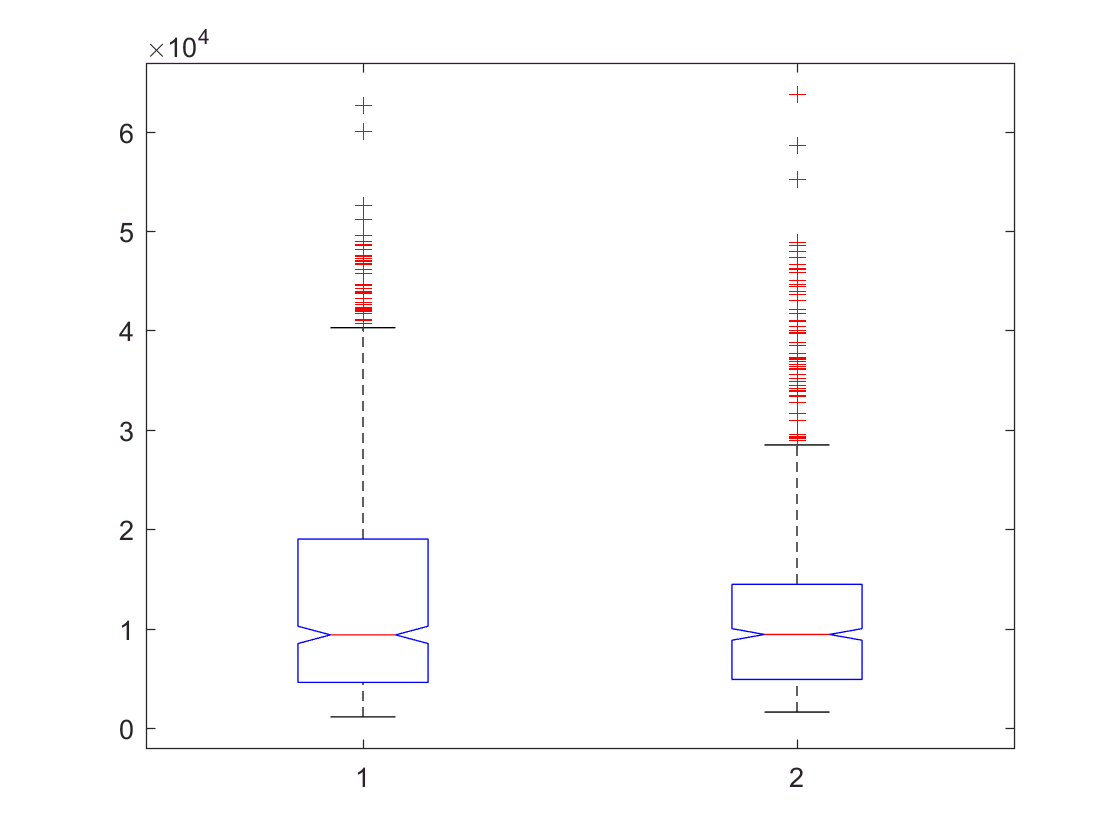

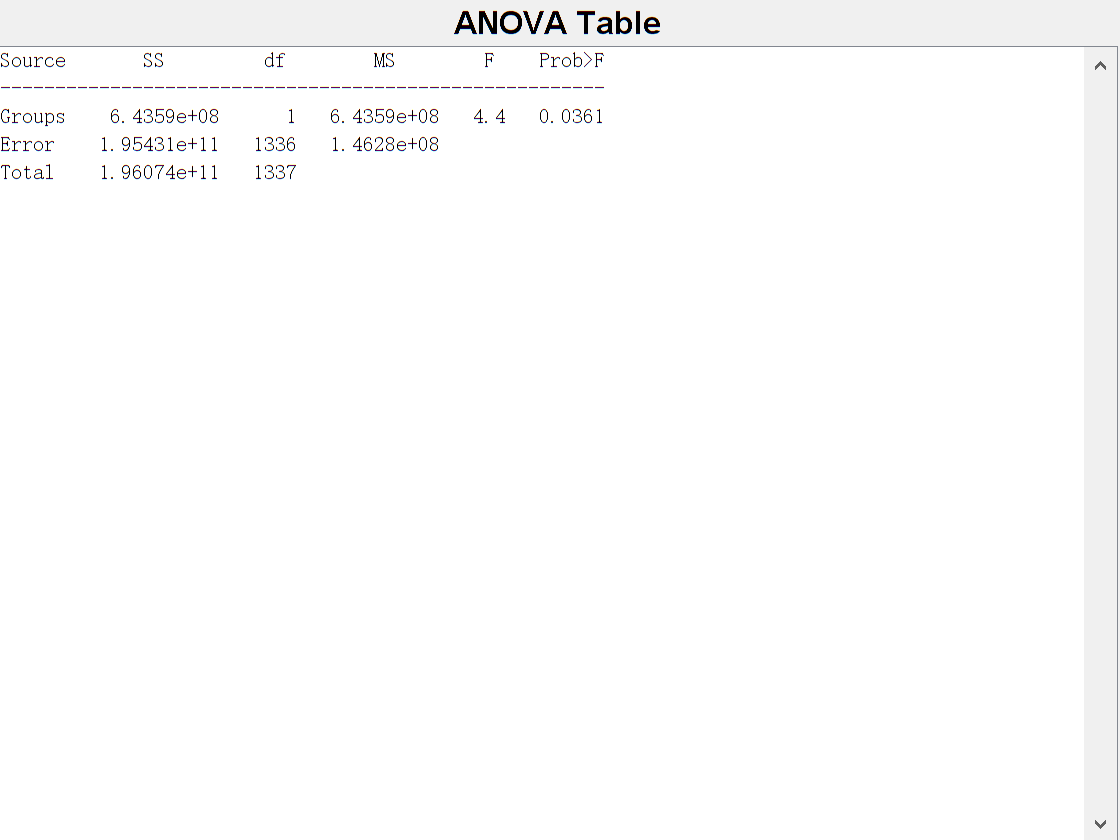

%清空数据
clear; clc;

%读取表格
%data_in_use即为要使用到的性别-医疗费用数据
data=readtable("data.txt");  
data_in_use=table2cell([data(:,2) data(:,7)]);
    
%读出男性女性分别的数据
%用all来计数，用group来表示数据的类别
%得到以上数据的原因是使用的函数为p=anova1(X,group)形式
%其中X指的是医疗费用，此时为样本中的第七列，为列向量
%其中group为医疗费用中元素的组别，为行向量
all=1;
for i=1:1338
    if(data_in_use{i}=="male")
        if(all==1)
            group=1;
        else
            group=[group 1];
        end
    else
        if(all==1)
            group=2;
        else
            group=[group 2];
        end
    end
    all=all+1;
end

%使用anova1()函数来计算得到p值
p=anova1(cell2mat(data_in_use(:,2)),group);